% Numerical Experiments

%% Reference case: base parameters and DP solution

clear; clc;

% Base case parameters 
params = base_case_params();          % w0, G, T, num_pf, rho_g, m, Sigma

% Efficient Frontier
[W, vmu, vsi, mu_vec] = compute_efficient_frontier( ...
    params.m, params.Sigma, params.num_pf, false); 

% Wealth grid (reference discretisation) 
nw_ref  = 327;        % Number of wealth nodes, chosen by paper.
ns_ref  = 3;          % Number of standard deviations 

[w_ref, lw_ref] = grid(params.w0, params.T, ...
    nw_ref, params.rho_g, vmu, vsi, params.G); 

% Transition probabilities:
[P_ref, ctpm_ref, start_ctpm_ref] = build_transitions(w_ref, params.w0, vmu, vsi);


% Dynamic Programming
tic;
[V_ref, policy_ref] = solve_dp(w_ref, params.G, params.T, P_ref);
time_dp_ref = toc;

% In-sample probabilities 
[prob_raw_ref, prob_inter_ref] = compute_success_probabilities(w_ref, params.w0, V_ref);

% ------------- Out-of-sample (OOS) probability -------------
Nsim_ref = 1e6;
tic;
[p_oos_ref, W_final_ref] = simulate_oos(w_ref, policy_ref, ...
    start_ctpm_ref, ctpm_ref, params.w0, params.G, params.T, Nsim_ref);
time_oos_ref = toc;


fprintf('REFERENCE CASE (nw=%d)\n', nw_ref);

REFERENCE CASE (nw=327)


fprintf('  In-sample (nearest)    = %.6f\n', prob_raw_ref);

  In-sample (nearest)    = 0.669206


fprintf('  In-sample (interp)     = %.6f\n', prob_inter_ref);

  In-sample (interp)     = 0.670204


fprintf('  OOS, %.0f simulations  = %.6f\n', Nsim_ref,p_oos_ref);

  OOS, 1000000 simulations  = 0.670151


fprintf('  DP time   (sec)        = %.3f\n', time_dp_ref);

  DP time   (sec)        = 0.067


fprintf('  OOS time  (sec)        = %.3f\n\n', time_oos_ref);

  OOS time  (sec)        = 10.316



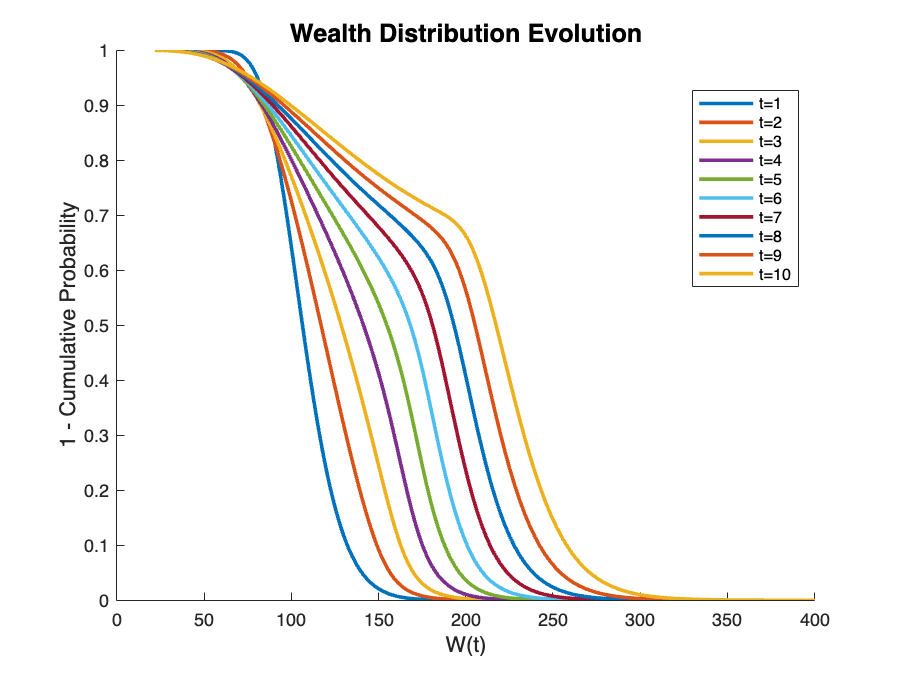


% Figure 2: Wealth Distribution Evolution 
CCDF_ref = compute_wealth_ccdf(w_ref, params.T, P_ref, policy_ref, params.w0);
plot_wealth_distribution(w_ref, CCDF_ref, params.T);

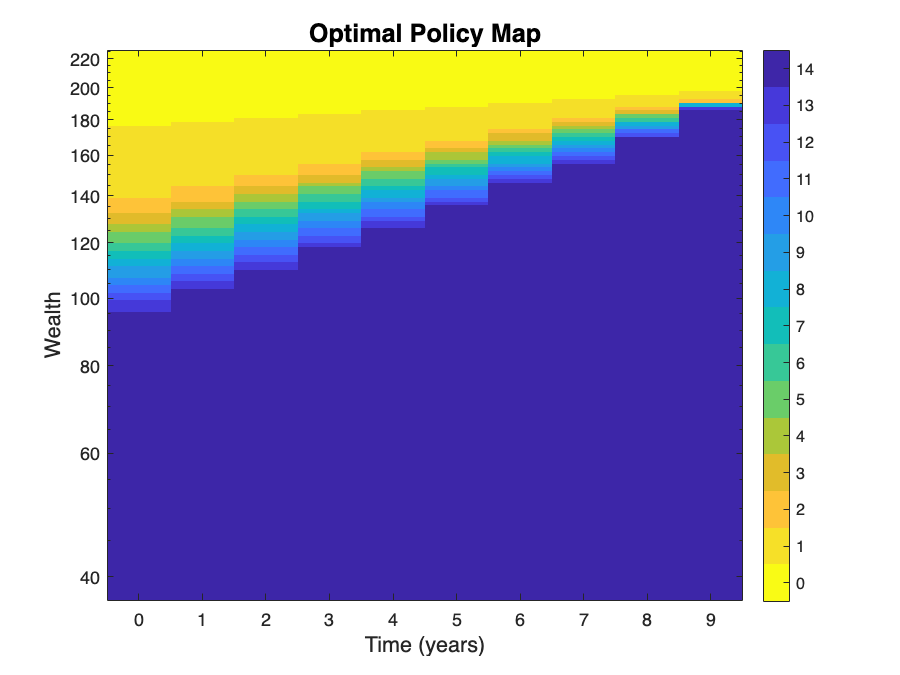


% Figure 4: Optimal Policy Map 
plot_policy_map(w_ref, policy_ref, params.num_pf);

% Experiment 1:

%% 1. Effect of wealth-grid discretisation (nw)

% Different wealth-grid sizes to test
nw_list = [100 200 327 500 800 1200];

Nsim_exp = 2e5; % fewer simulations as that'd take a while...

results_nw = struct('nw', [], 'prob_raw', [], 'prob_inter', [], ...
                    'p_oos', [], 'time_dp', [], 'time_oos', []);

for k = 1:numel(nw_list)
    nw = nw_list(k);
    fprintf('--- Running nw = %d ---\n', nw);

    % Wealth grid for this nw
    [w, lw] = grid(params.w0, params.T, ...
        nw, params.rho_g, vmu, vsi, params.G); 

    % Transition probabilities
    [P, ctpm, start_ctpm] = build_transitions(w, params.w0, vmu, vsi);

    % DP solve
    tic;
    [V, policy] = solve_dp(w, params.G, params.T, P);
    time_dp = toc;

    % In-sample probabilities
    [prob_raw, prob_inter] = compute_success_probabilities(w, params.w0, V);

    % OOS simulation
    tic;
    [p_oos, W_final] = simulate_oos(w, policy, start_ctpm, ctpm, ...
        params.w0, params.G, params.T, Nsim_exp); 

    time_oos = toc;

    % Store results
    results_nw(k).nw          = nw;
    results_nw(k).prob_raw    = prob_raw;
    results_nw(k).prob_inter  = prob_inter;
    results_nw(k).p_oos       = p_oos;
    results_nw(k).time_dp     = time_dp;
    results_nw(k).time_oos    = time_oos;
end

--- Running nw = 100 ---
--- Running nw = 200 ---
--- Running nw = 327 ---
--- Running nw = 500 ---
--- Running nw = 800 ---
--- Running nw = 1200 ---



% Turn into a table for easy viewing
nw_values      = [results_nw.nw]';
prob_raw_nw    = [results_nw.prob_raw]';
prob_inter_nw  = [results_nw.prob_inter]';
p_oos_nw       = [results_nw.p_oos]';
time_dp_nw     = [results_nw.time_dp]';
time_oos_nw    = [results_nw.time_oos]';

table_nw = table(nw_values, prob_raw_nw, prob_inter_nw, ...
    p_oos_nw, time_dp_nw, time_oos_nw, ...
    'VariableNames', {'nw', 'ProbRaw', 'ProbInterp', ...
    'ProbOOS', 'DP_Time', 'OOS_Time'})

table_nw = 6×6 table
     nw     ProbRaw    ProbInterp    ProbOOS    DP_Time     OOS_Time
    ____    _______    __________    _______    ________    ________

     100    0.68397     0.67148      0.67092    0.015659     1.5502 
     200    0.67648     0.67033      0.67056    0.019294       1.73 
     327    0.66921      0.6702        0.669    0.041329     2.1415 
     500     0.6725     0.67012      0.66863    0.073555     2.5534 
     800    0.67154     0.67009       0.6707     0.25258     3.7309 
    1200    0.67102     0.67008      0.66878     0.64441     10.331 


%% Experiment 2:

% 2. Effect of the number of standard deviations (ns)

ns_list = [1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0];
nw_ns   = nw_ref;    % keep nw fixed at the reference value

results_ns = struct('ns', [], 'prob_raw', [], 'prob_inter', [], ...
                    'p_oos', [], 'time_dp', [], 'time_oos', []);

for k = 1:numel(ns_list)
    ns = ns_list(k);
    fprintf('--- Running ns = %.1f ---\n', ns);

    % Wealth grid with different ns
    [w, lw] = grid(params.w0, params.T, ...
        nw_ns, ns, vmu, vsi, params.G); 

    % Transition probabilities
    [P, ctpm, start_ctpm] = build_transitions(w, params.w0, vmu, vsi);

    % DP solve
    tic;
    [V, policy] = solve_dp(w, params.G, params.T, P);
    time_dp = toc;

    % In-sample probabilities
    [prob_raw, prob_inter] = compute_success_probabilities(w, params.w0, V);

    % OOS simulation
    tic;
    [p_oos, W_final] = simulate_oos(w, policy, start_ctpm, ctpm, ...
        params.w0, params.G, params.T, Nsim_exp);
    time_oos = toc;

    % Store results
    results_ns(k).ns          = ns;
    results_ns(k).prob_raw    = prob_raw;
    results_ns(k).prob_inter  = prob_inter;
    results_ns(k).p_oos       = p_oos;
    results_ns(k).time_dp     = time_dp;
    results_ns(k).time_oos    = time_oos;
end

--- Running ns = 1.0 ---
--- Running ns = 1.5 ---
--- Running ns = 2.0 ---
--- Running ns = 2.5 ---
--- Running ns = 3.0 ---
--- Running ns = 3.5 ---
--- Running ns = 4.0 ---
--- Running ns = 4.5 ---
--- Running ns = 5.0 ---



% Turn into a table
ns_values      = [results_ns.ns]';
prob_raw_ns    = [results_ns.prob_raw]';
prob_inter_ns  = [results_ns.prob_inter]';
p_oos_ns       = [results_ns.p_oos]';
time_dp_ns     = [results_ns.time_dp]';
time_oos_ns    = [results_ns.time_oos]';

table_ns = table(ns_values, prob_raw_ns, prob_inter_ns, ...
    p_oos_ns, time_dp_ns, time_oos_ns, ...
    'VariableNames', {'ns', 'ProbRaw', 'ProbInterp', ...
    'ProbOOS', 'DP_Time', 'OOS_Time'})

table_ns = 9×6 table
    ns     ProbRaw    ProbInterp    ProbOOS    DP_Time     OOS_Time
    ___    _______    __________    _______    ________    ________

      1    0.72108     0.72183      0.72086    0.072743     2.1406 
    1.5    0.67567      0.6738      0.67636    0.048765     2.1114 
      2    0.67101     0.67023      0.67214    0.043802     2.1059 
    2.5     0.6686     0.67015      0.66953    0.045799     2.0834 
      3    0.66921      0.6702      0.67128     0.04785     2.1121 
    3.5    0.66501     0.67021      0.66982    0.046929     2.0954 
      4    0.67028     0.67029      0.67002    0.042595      2.072 
    4.5    0.66302     0.67025       0.6708    0.041743      2.089 
      5    0.66977     0.67038      0.67217    0.052942      2.089 


--- Policy plot for nw = 50 ---


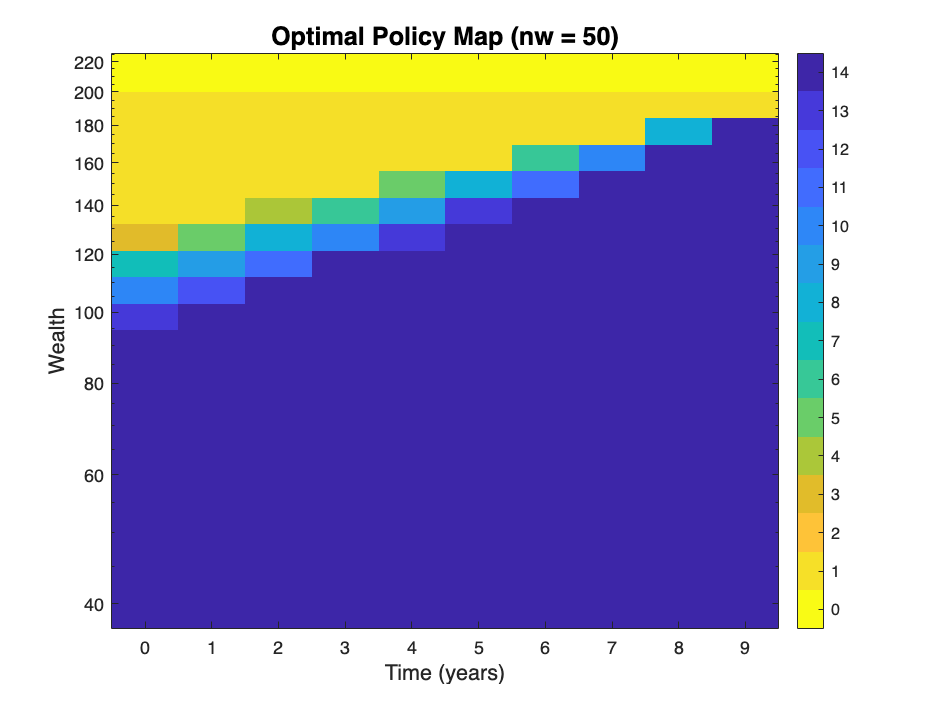

--- Policy plot for nw = 327 ---


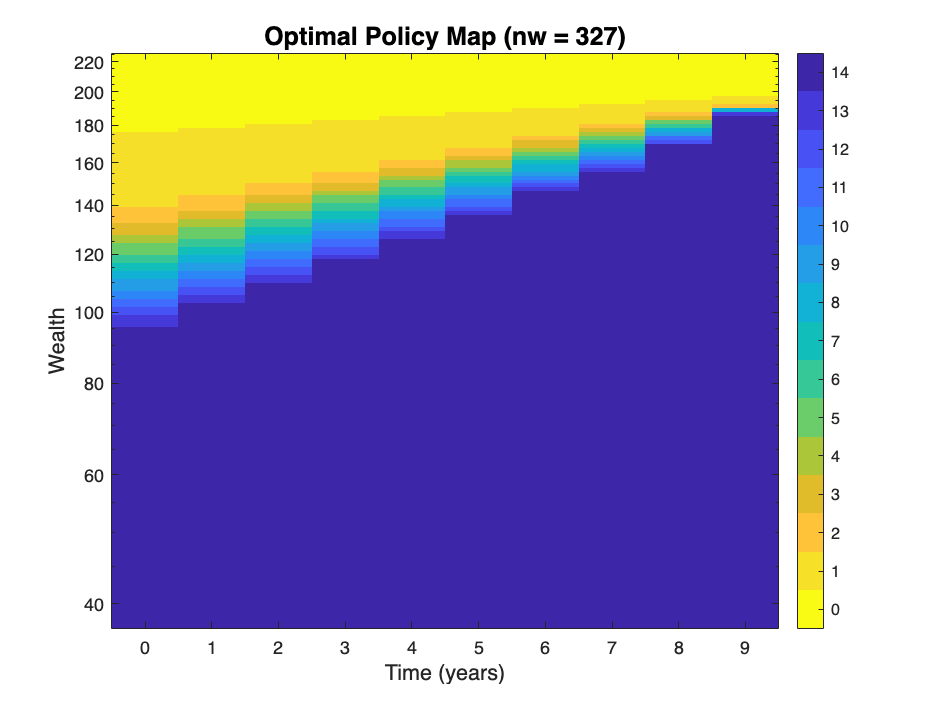

--- Policy plot for nw = 1200 ---


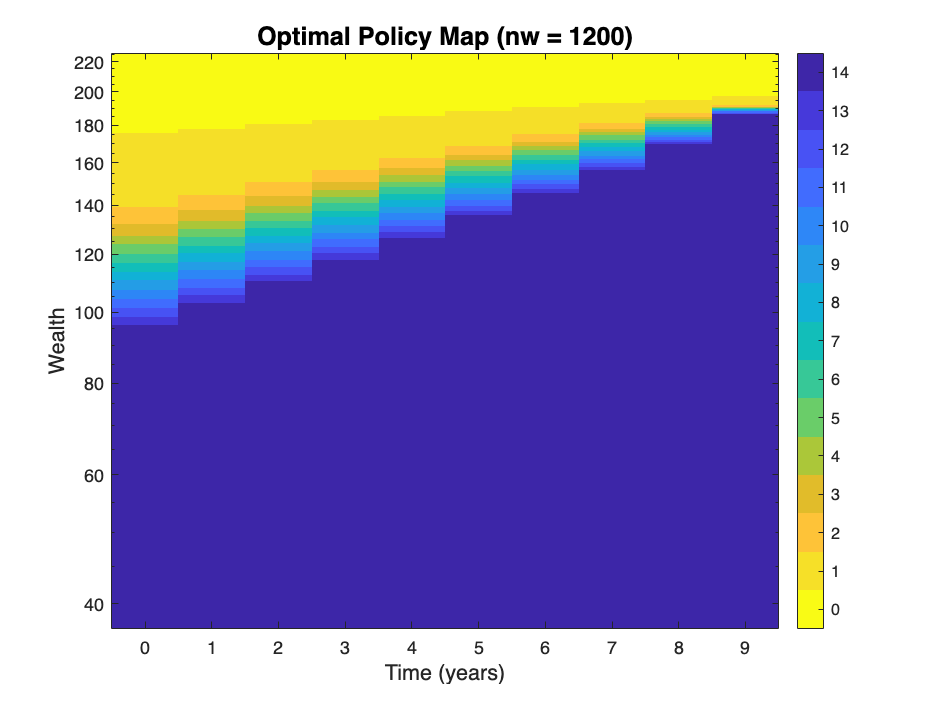

% Visual checks!

%% 3. Quick visual comparison of policies for different nw (optional)

% Can compare different nw values, here 50, 327, 1200

nw_compare = [50 327 1200];

for k = 1:numel(nw_compare)
    nw = nw_compare(k);
    fprintf('--- Policy plot for nw = %d ---\n', nw);

    [w, lw] = grid(params.w0, params.T, ...
        nw, params.rho_g, vmu, vsi, params.G); 
    [P, ctpm, start_ctpm] = build_transitions(w, params.w0, vmu, vsi);
    [V, policy] = solve_dp(w, params.G, params.T, P); 

    plot_policy_map(w, policy, params.num_pf);
    title(sprintf('Optimal Policy Map (nw = %d)', nw));
end